Note: should be run from the src folder

Decomposes auto correlation and its second derivative into elongation and dynamic contribution. The elongation contribution is the contribution to the auto correlation from subsequent points in a trace sharing RNA polymerases. The dyanmics contribution comes from the time it takes for a given nucleus to shift initiation rates.

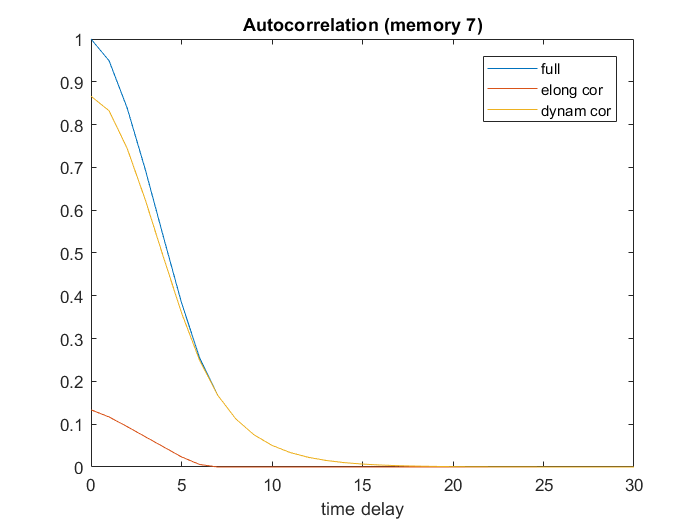

% auto correlation decomposition

cor_tots = [];
elong_tots = [];
dynam_tots = [];

for i = 0:30
    [cor_tot,pois] = full_func_cor_theory(7,2,i,2,.4);
    cor_tots = [cor_tots cor_tot];
    elong_tots = [elong_tots, pois];
    dynam_tots = [dynam_tots cor_tot - pois];
end

dynam_tots = dynam_tots / cor_tots(1);
elong_tots = elong_tots / cor_tots(1);
cor_tots = cor_tots /  cor_tots(1);
figure()
plot(0:30, cor_tots)
hold on
plot(0:30, elong_tots)
hold on
plot(0:30, dynam_tots)
legend({'full', 'elong cor', 'dynam cor'})
title('Autocorrelation (memory 7)')
xlabel('time delay')

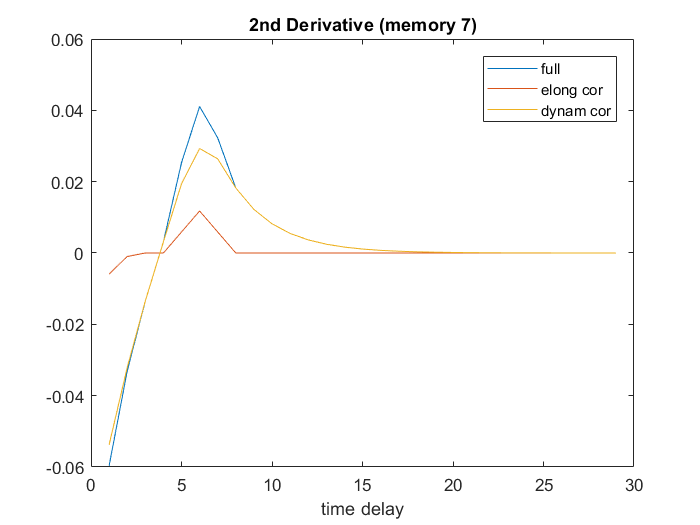


deriv1 = cor_tots(2:end) - cor_tots(1:end-1); 
deriv1_elong = elong_tots(2:end) - elong_tots(1:end-1);
deriv1_dynam = dynam_tots(2:end) - dynam_tots(1:end-1);

deriv2 = deriv1(2:end) - deriv1(1:end-1);
deriv2_elong = deriv1_elong(2:end) - deriv1_elong(1:end-1);
deriv2_dynam = deriv1_dynam(2:end) - deriv1_dynam(1:end-1);

figure()
plot(deriv2)
hold on
plot(deriv2_elong)
hold on
plot(deriv2_dynam)
legend({'full', 'elong cor', 'dynam cor'})
title('2nd Derivative (memory 7)')
xlabel('time delay')

Plots full autocorrelation and full second derivative on the same plot.

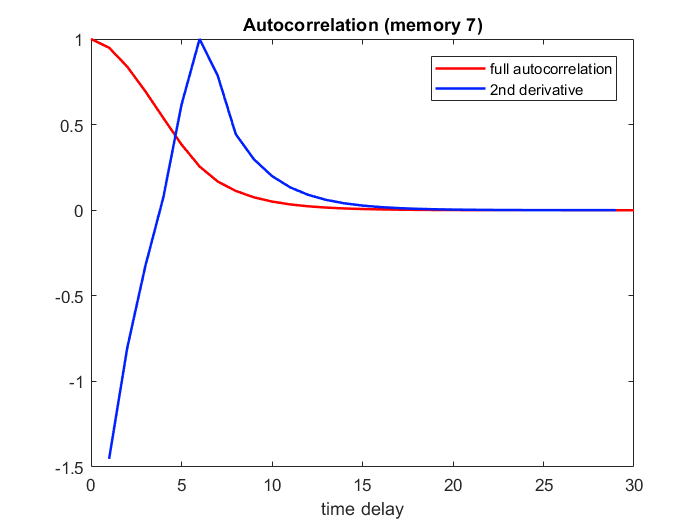

% full autocorrelation and second derivative on same plot

cor_tots = [];


for i = 0:30
    [cor_tot,pois] = full_func_cor_theory(7,2,i,2,.4);
    cor_tots = [cor_tots cor_tot];
end

cor_tots = cor_tots /  cor_tots(1);
figure()
plot(0:30, cor_tots, 'Color', 'r', 'LineWidth', 1.5)
hold on

title('Autocorrelation (memory 7)')
xlabel('time delay')

deriv1 = cor_tots(2:end) - cor_tots(1:end-1); 
deriv2 = deriv1(2:end) - deriv1(1:end-1);
deriv2 = deriv2 / max(deriv2);

cm = jet(64);
plot(deriv2,'Color',cm(10,:),'LineWidth',1.5)

legend({'full autocorrelation', '2nd derivative'})